clc ; clear; 

%% Battery simulation, made for end-point device,
% Tom Takken, 2025.

% Voltage converter specifications
V2Vefficiency = .95;

% Battery specifications
batteryVoltage = 3.7; %V (nominal!)
measuredVoltage = 5; %V
batteryCharge = 3500; %mAh! [C]

% ESP settings:
waitDuration = 54; %seconds between sleep (sensor off) and wake up

% Measurements in mA, milliseconds.

        % seconds to ms
    s2ms = 1000;
    ms2s = 1/1000;
baselineCurrent = 6.5; %NOTE: contains an LED.

CO2SensorCurrent = 9.2; % when sensor turned on after send

transmissionCurrent = 75.4; % when transmission RSSI
transmissionDuration = 1.18 * s2ms; % in ms

    % approximated peak values

    % peak to rms approximation

    % this is not something that we actually have,
    % however as the function is not quite a step and
    % not quite a triangle, this is an approximation
pk2rms = 1/(sqrt(2) + 0.2); %From a sinusoid function + a bit for a better fit;

% nearly square peak, immediately after transmission (sleep / measure)
secondaryPeak = 120 * pk2rms; % approximated, peak value of nearly rectangle
beginSecPeak = 1.2 * 2 * s2ms; % measured from begin of 1st peak, seconds -> ms
secPeakDuration = 550; % 550ms

% triangular peak, last before cycle (wake up peak)
tertiaryPeak = 160/2 * pk2rms; % approximated, avg peak value of triangle
beginTertPeak = 4.5 * 2 * s2ms; % measured from begin of 1st peak, seconds -> ms
tertPeakDuration = 7 * 20 ; %140 ms



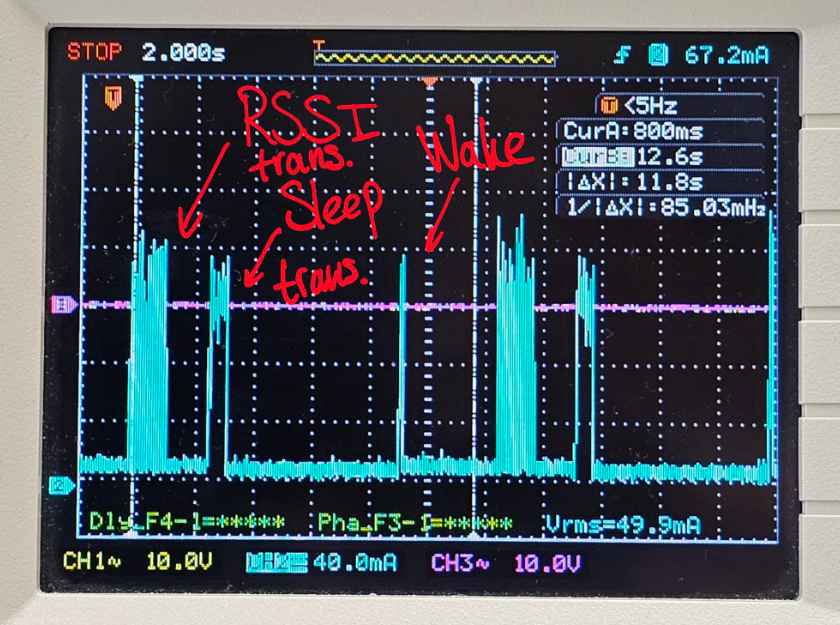

%% Simulation of one cycle
% We start at the RSSI transmission as seen above.

% Making current array that corresponds with expected values 
% (index is in milliseconds!)

    % Peak values
transmissionArray = transmissionCurrent * ones(1,transmissionDuration);
% device transmits RSSI, Temp
secondaryPeakArray = secondaryPeak * ones(1, secPeakDuration);
% device goes to sleep
tertiaryPeakArray = tertiaryPeak * ones(1,tertPeakDuration);
% device goes to wake

    % Intermittent times
% between sleep peak and wake peak is
lowPowerSleepDuration = waitDuration*s2ms;

% between RSSI and sleep peak is 
postTransSensDuration = beginSecPeak-transmissionDuration;

% between wake and RSSI transmission is
toRSSIDuration = 1.8 * 2 * s2ms; %from image above

    % Intermittent values

% between sleep & next wake up is waitDuration seconds
lowPowerSleepArray = baselineCurrent * ones(1,lowPowerSleepDuration);
RSSItoSleepArray = CO2SensorCurrent * ones(1,postTransSensDuration);
wakeToRSSIArray = CO2SensorCurrent * ones(1,toRSSIDuration);

% Timeline assembly:
% RSSIpeak -> RSSI2Sleep -> SleepPeak -> 
% DeepSleep -> WakePeak -> WaketoRSSI

currentArray = [transmissionArray,RSSItoSleepArray, secondaryPeakArray, ...
    lowPowerSleepArray, tertiaryPeakArray, wakeToRSSIArray];


%% Calculating projected lifespans

% Our power draw will be equivalent to the power drawn from the battery,
% assuming an efficiency.

% for any current drawn here, we know that Pmeas = Pbat * eff, so
% IV_meas / eff = IbatVbat
% Ibat = IV_meas / eff * Vbat = Imeas * (Vmeas / (eff * Vbat))

batteryCurrentArray = currentArray * ...
(measuredVoltage / (V2Vefficiency * batteryVoltage));

% if we integrate over this, we find that int(...) = mA * ms,
% so an answer in microcoulombs.

% a milliAmpHour is 3.6 coulomb.

chargeUsed = trapz(batteryCurrentArray); % microcoulomb

chargeUsedmAh = (chargeUsed / ((10^6) * 3.6)); % mAh

nCycles = floor(batteryCharge / chargeUsedmAh);
cycleLength = length(currentArray) * ms2s;

EnduranceTime = (nCycles*cycleLength)/(3600*24); %days
disp("This battery with provided cycle information will approximately last " + EnduranceTime + " days")

This battery with provided cycle information will approximately last 11.6927 days


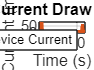

%% Plotting
time_s = (1:length(currentArray)) * ms2s;

% Create a new figure window for the plot
figure;

% Plot the current over time with a slightly thicker line for visibility
plot(time_s, currentArray, 'LineWidth', 2,'Color',[0.850, 0.325, 0.098]);

% Add labels and a title to make the plot informative
title('Simulated Current Draw Over One Cycle');
xlabel('Time (s)');
ylabel('Current (mA)');

% Add a grid and legend for better readability
grid on;
legend('Device Current');

% Ensure the x-axis starts at zero
xlim([0, max(time_s)]);